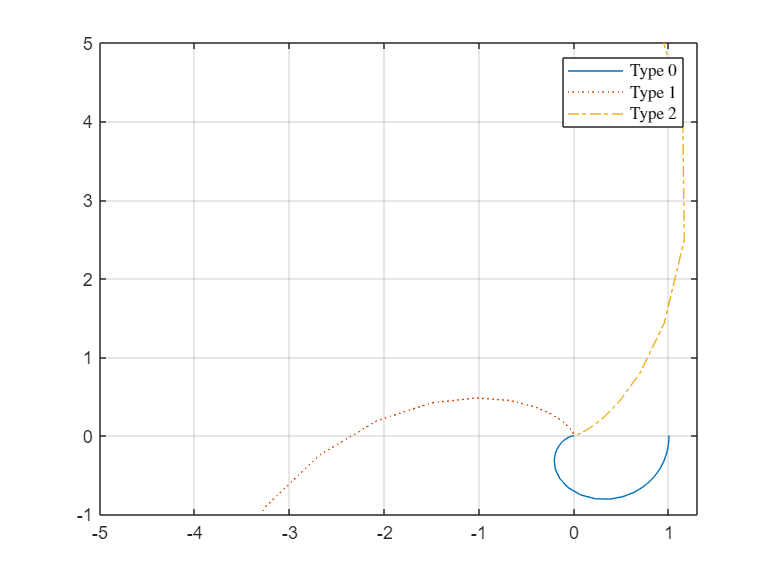

clear all;
close all;
clc


s = tf('s');

wn =0.3; eta=0.7;
P1 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
[re1,im1,w1]=nyquist(P1);

wn =0.3; eta=0.7;
P2 = wn*wn/(s*(s*s+ 2*eta*s*wn+ wn*wn));
[re2,im2,w2]=nyquist(P2);

wn =0.3; eta=0.7;
P3 = wn*wn/(s*s*(s*s+ 2*eta*s*wn+ wn*wn));
[re3,im3,w3]=nyquist(P3);

figure;
plot(squeeze(re1),squeeze(im1),'-', ...
     squeeze(re2),squeeze(im2),':', ...
     squeeze(re3),squeeze(im3),'-.')
hh = legend('Type $0$','Type $1$','Type $2$');
set(hh,'Interpreter','latex'); 
axis([-5,1.3,-1,5]); grid on;

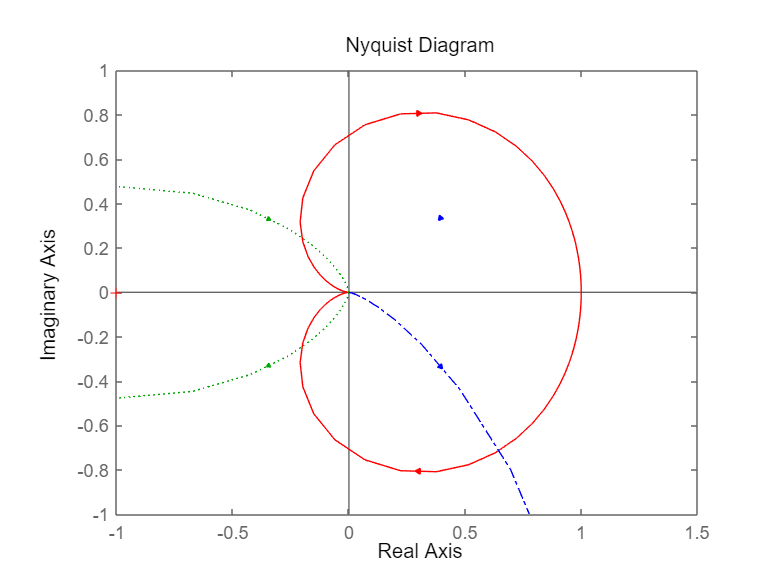


nyquistplot(P1,'r-',P2,'g:',P3,'b-.');axis([-1,1.5,-1,1])